# `实验二：调节器参数变化对控制过程的影响`

`选取一阶惯性环节加滞后环节建模，通过实验测试法获取传递函数参数。`

tau=35;
T=37;
K=0.64;
s=tf('s');
W=exp(-s*tau)*K/(T*s+1);
Ts=1;
W=c2d(W,Ts);
%use the state-space representation for more efficient modeling of discrete-time delays
W=ss(W);

## 不同控制器比较

比较纯比例，PI，PD，PID控制器的控制效果

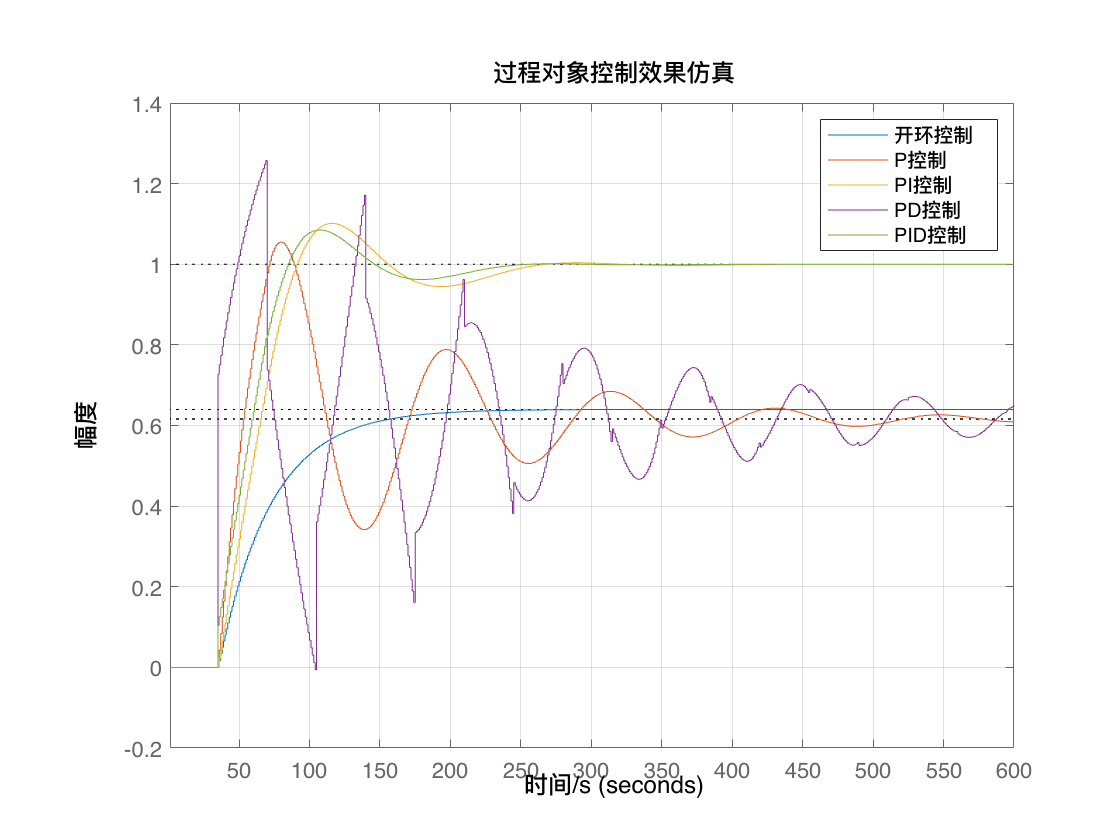

C={'开环','P','PI','PD','PID'};
ess=zeros(1,5);
figure()
hold on;
t=1:600;
stepplot(W,t);
y=step(W,t);
info=stepinfo(y,t);
s=repmat(info,1,5);
ess(1)=1-y(end);

%pid反馈控制
for i=2:5
    Gc=pidtune(W,C{i});
    Gc=pidstd(Gc);
    Phi=feedback(series(Gc,W),1);
    stepplot(Phi,t);
    y=step(Phi,t);
    s(i)=stepinfo(y,t);
    ess(i)=1-y(end);
end
legend(C+"控制")
grid;xlabel("时间/s");ylabel("幅度")
title("过程对象控制效果仿真");

T = table( ...
    [s.RiseTime]',[s.PeakTime]',[s.SettlingTime]', ...
    [s.Overshoot]',ess',...
  'VariableNames',{'上升时间','峰值时间','调节时间','超调量','稳态误差'},...
  'RowNames',C');
display(T)

T = 5×5 table
            上升时间    峰值时间    调节时间    超调量      稳态误差  
            _______    _______    _______    ______    __________

    开环    81.298       600      179.75          0          0.36
    P       14.073        79      567.03      73.33       0.39138
    PI      42.262       115      237.69     10.135    2.8138e-05
    PD      0.7138        69       594.6      93.67       0.35089
    PID      40.35       107       212.8     8.4915    4.6153e-06


Gc =
 
             1       Ts  
  Kp * (1 + ---- * ------)
             Ti      z-1 

  with Kp = 1.3, Ti = 49.9, Ts = 1
 
Sample time: 1 seconds
Discrete-time PI controller in standard form



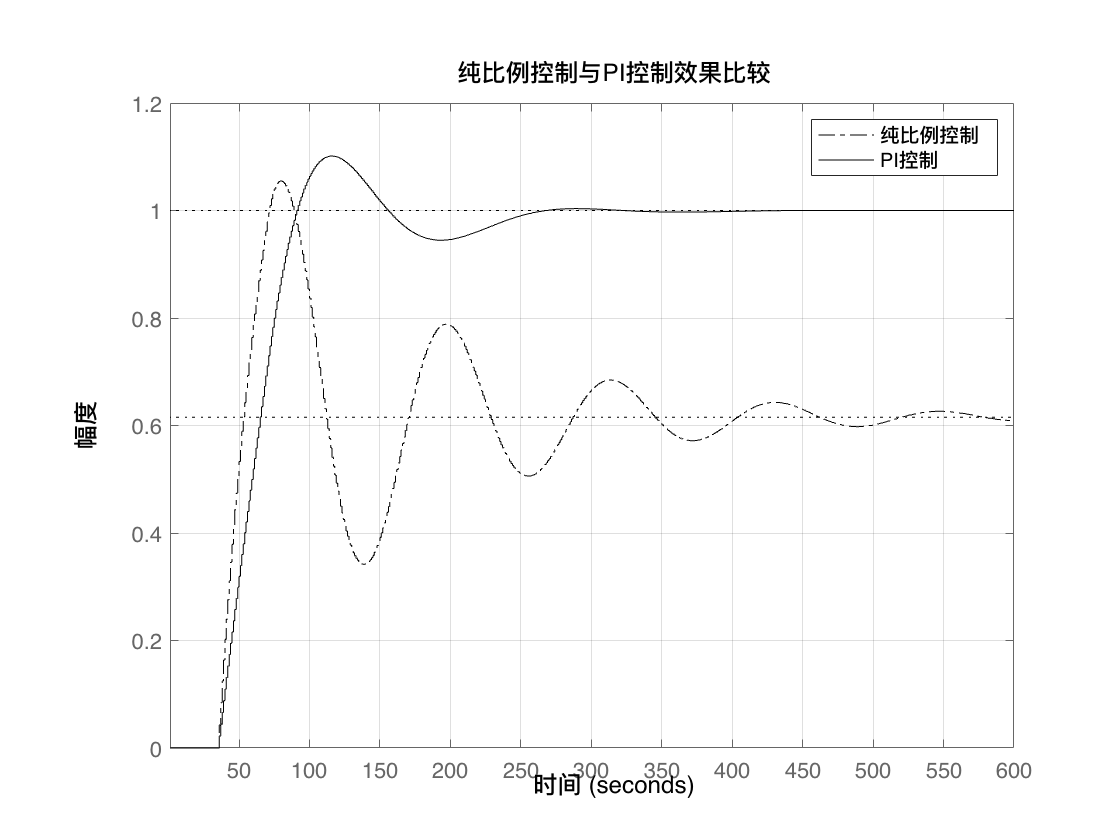

Gc =
 
                   z-1 
  Kp * (1 + Td * ------)
                   Ts  

  with Kp = 2.51, Td = 17, Ts = 1
 
Sample time: 1 seconds
Discrete-time PD controller in standard form



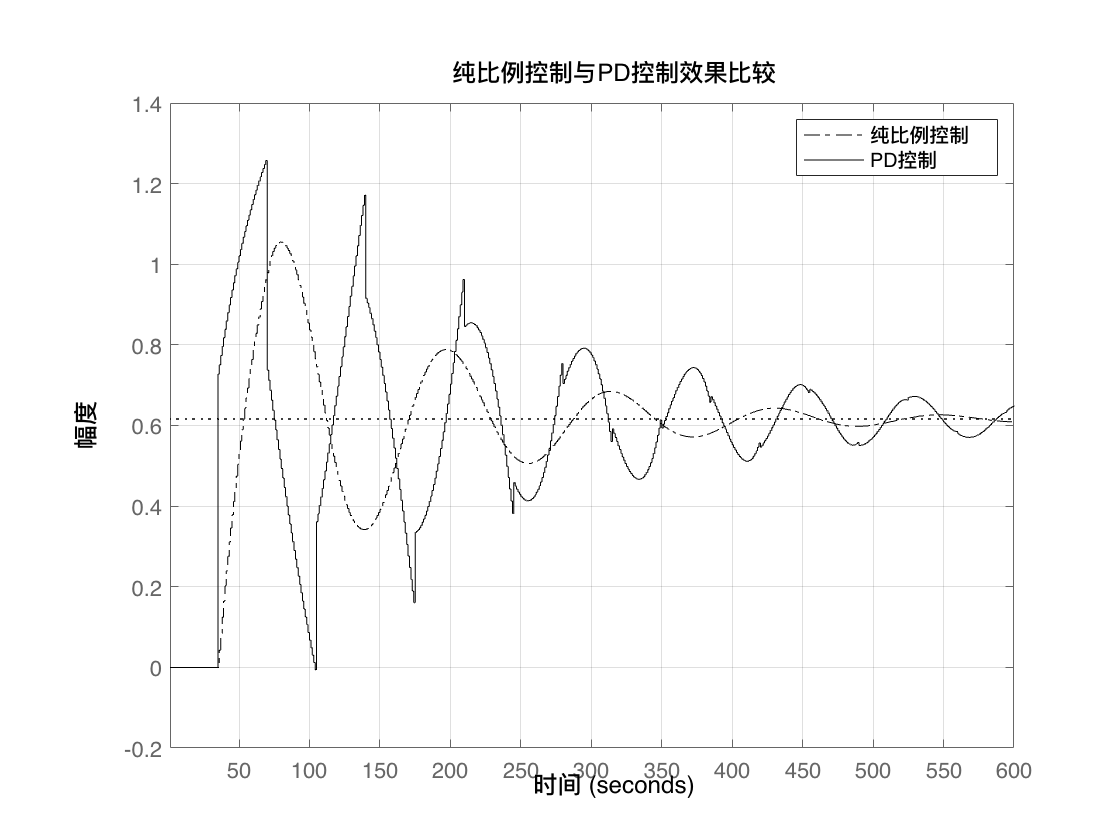

Gc1=pidtune(W,"P");
Phi1=feedback(series(Gc1,W),1);
%pid反馈控制
for i=3:4
    figure()
    hold on
    
    stepplot(Phi1,t,'k-.');

    Gc=pidtune(W,C{i});
    Gc=pidstd(Gc)
    Phi=feedback(series(Gc,W),1);
    stepplot(Phi,t,'k-');
    legend("纯比例控制",C(i)+"控制")
    grid;xlabel("时间");ylabel("幅度");
    title("纯比例控制与"+C(i)+"控制效果比较")
end

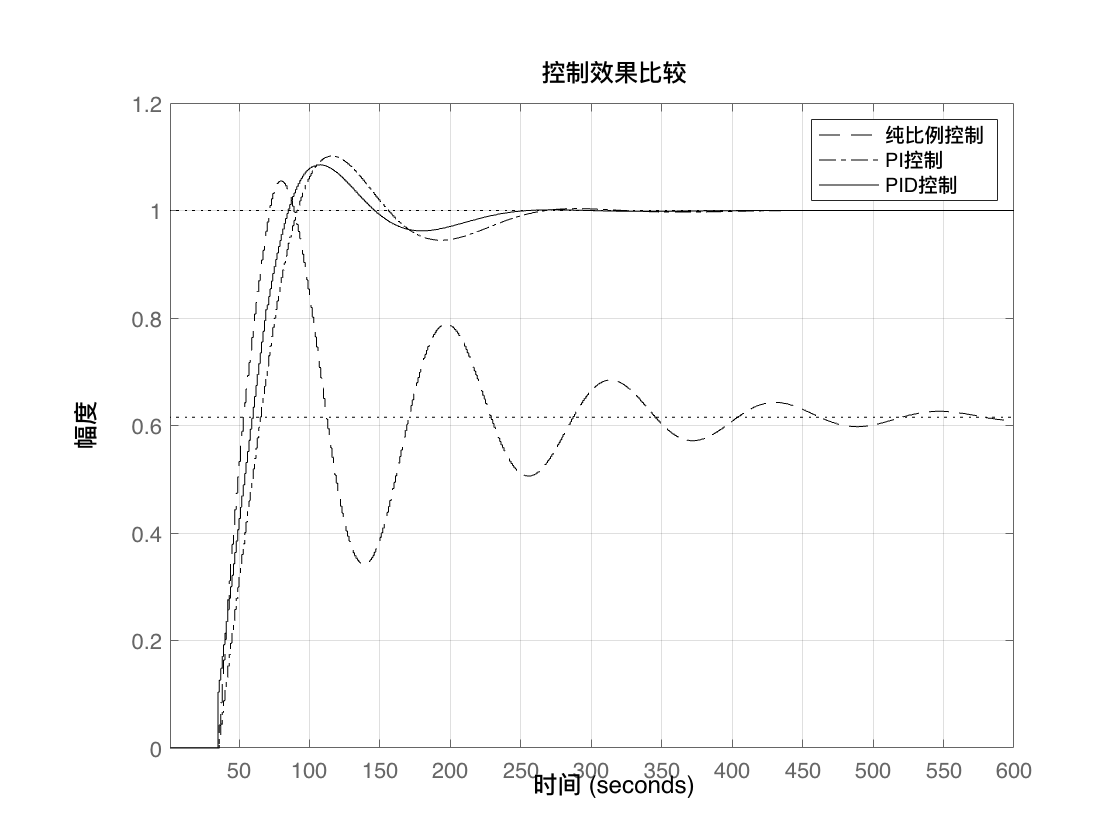

figure()
hold on;
specs="k"+["--","-.","-"];
pids=["P","PI","PID"];
for i=1:3
    Gc=pidtune(W,pids(i));
    Gc=pidstd(Gc);
    Phi=feedback(series(Gc,W),1);
    stepplot(Phi,t,specs(i));
end
legend("纯比例控制","PI控制","PID控制")
grid;xlabel("时间");ylabel("幅度");
title("控制效果比较")

## 不同控制器参数比较

使用自带函数整定PID控制器

Gpid=pidtune(W,"PID");
Gpid=pidstd(Gpid)

Gpid =
 
             1       Ts            z-1 
  Kp * (1 + ---- * ------ + Td * ------)
             Ti      z-1           Ts  

  with Kp = 1.46, Ti = 50.5, Td = 4.18, Ts = 1
 
Sample time: 1 seconds
Discrete-time PID controller in standard form



### 增大或减小比例度

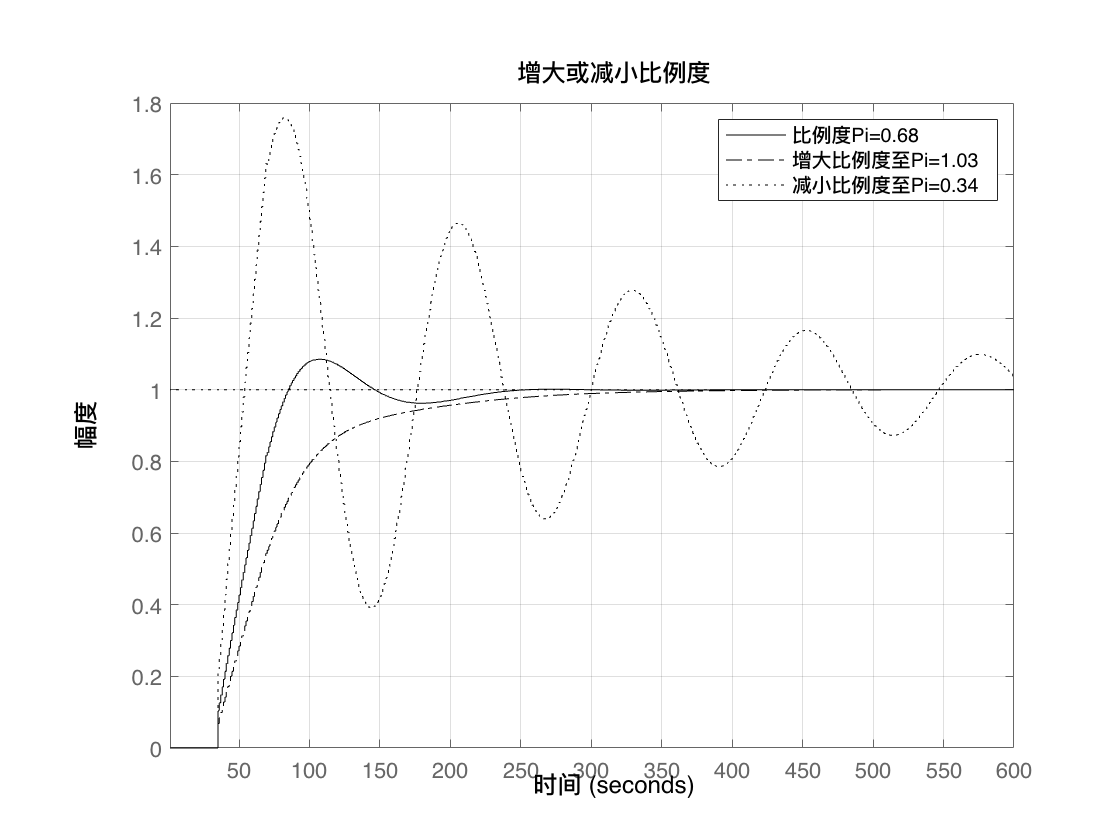

Pi=1/Gpid.Kp;
Pi_inc=Pi*1.5;
Pi_dec=Pi*0.5;
figure();hold on;
Phi=feedback(series(Gpid,W),1);
Phi1=feedback(series(pidstd(1/Pi_inc,Gpid.Ti,Gpid.Td,Inf,Ts),W),1);
Phi2=feedback(series(pidstd(1/Pi_dec,Gpid.Ti,Gpid.Td,Inf,Ts),W),1);
stepplot(Phi,"k-",t);
stepplot(Phi1,"k-.",t);
stepplot(Phi2,"k:",t);
grid;xlabel("时间");ylabel("幅度");
title("增大或减小比例度");
label=[
    sprintf("比例度Pi=%.2f",Pi);
    sprintf("增大比例度至Pi=%.2f",Pi_inc);
    sprintf("减小比例度至Pi=%.2f",Pi_dec)
];
legend(label)

T=[struct2table(stepinfo(Phi));struct2table(stepinfo(Phi1));struct2table(stepinfo(Phi2))];
T.Properties.RowNames=label;
T

T = 3×9 table
                         RiseTime    TransientTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak      PeakTime
                         ________    _____________    ____________    ___________    ___________    _________    __________    _______    ________

    比例度Pi=0.68            41            213             213           0.90883         1.0849        8.491          0          1.0849      107   
    增大比例度至Pi=1.03       97            258             258           0.90123        0.99997            0          0         0.99997      709   
    减小比例度至Pi=0.34       17            952             952           0.39117         1.7586       75.857          0          1.7586       82   


### 增大或减小积分时间常数

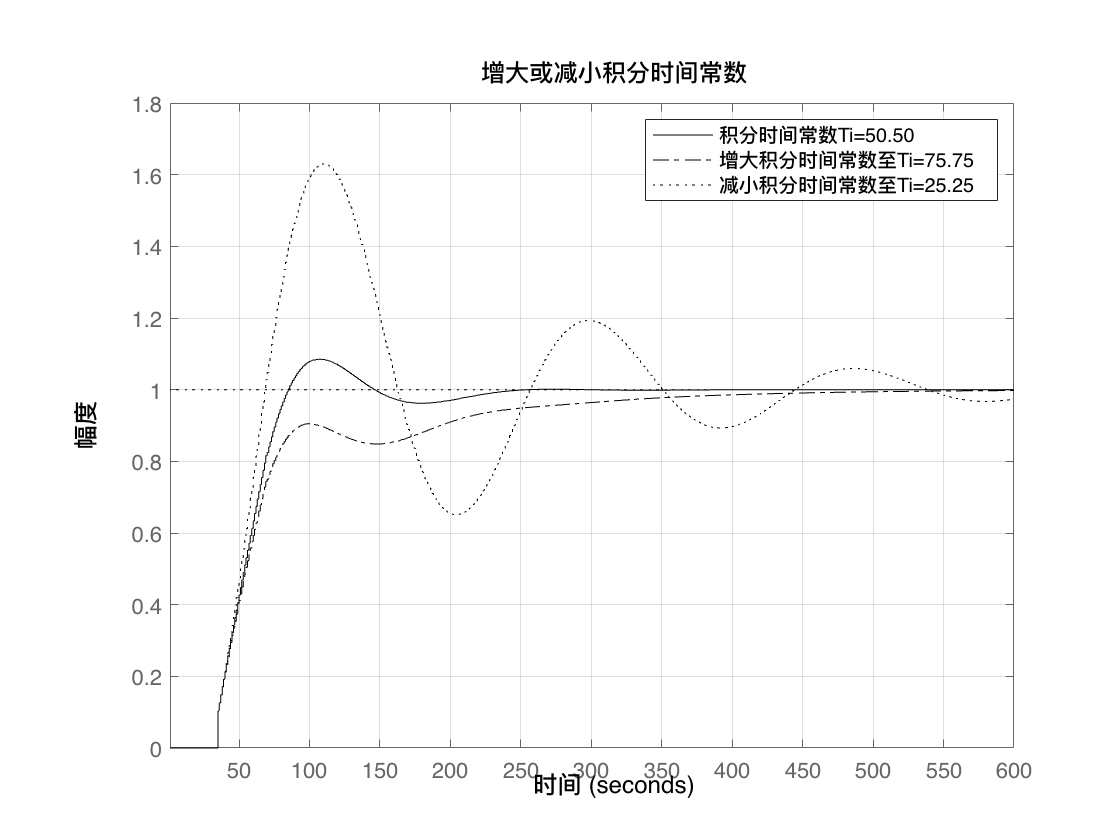

Ti=Gpid.Ti;
Ti_inc=Ti*1.5;
Ti_dec=Ti*0.5;
figure();hold on;
Phi=feedback(series(Gpid,W),1);
Phi1=feedback(series(pidstd(Gpid.Kp,Ti_inc,Gpid.Td,Inf,Ts),W),1);
Phi2=feedback(series(pidstd(Gpid.Kp,Ti_dec,Gpid.Td,Inf,Ts),W),1);
stepplot(Phi,"k-",t)
stepplot(Phi1,"k-.",t)
stepplot(Phi2,"k:",t);
grid;xlabel("时间");ylabel("幅度");
title("增大或减小积分时间常数")
label=[
    sprintf("积分时间常数Ti=%.2f",Ti);
    sprintf("增大积分时间常数至Ti=%.2f",Ti_inc);
    sprintf("减小积分时间常数至Ti=%.2f",Ti_dec)];
legend(label)

T=[struct2table(stepinfo(Phi));struct2table(stepinfo(Phi1));struct2table(stepinfo(Phi2))];
T.Properties.RowNames=label;
T

T = 3×9 table
                               RiseTime    TransientTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak      PeakTime
                               ________    _____________    ____________    ___________    ___________    _________    __________    _______    ________

    积分时间常数Ti=50.50            41            213             213           0.90883         1.0849        8.491          0          1.0849      107   
    增大积分时间常数至Ti=75.75       59            362             362           0.84837        0.99974            0          0         0.99974      849   
    减小积分时间常数至Ti=25.25       30            609             609            0.6512           1.63       63.003          0            1.63      110   


### 增大或减小微分时间常数

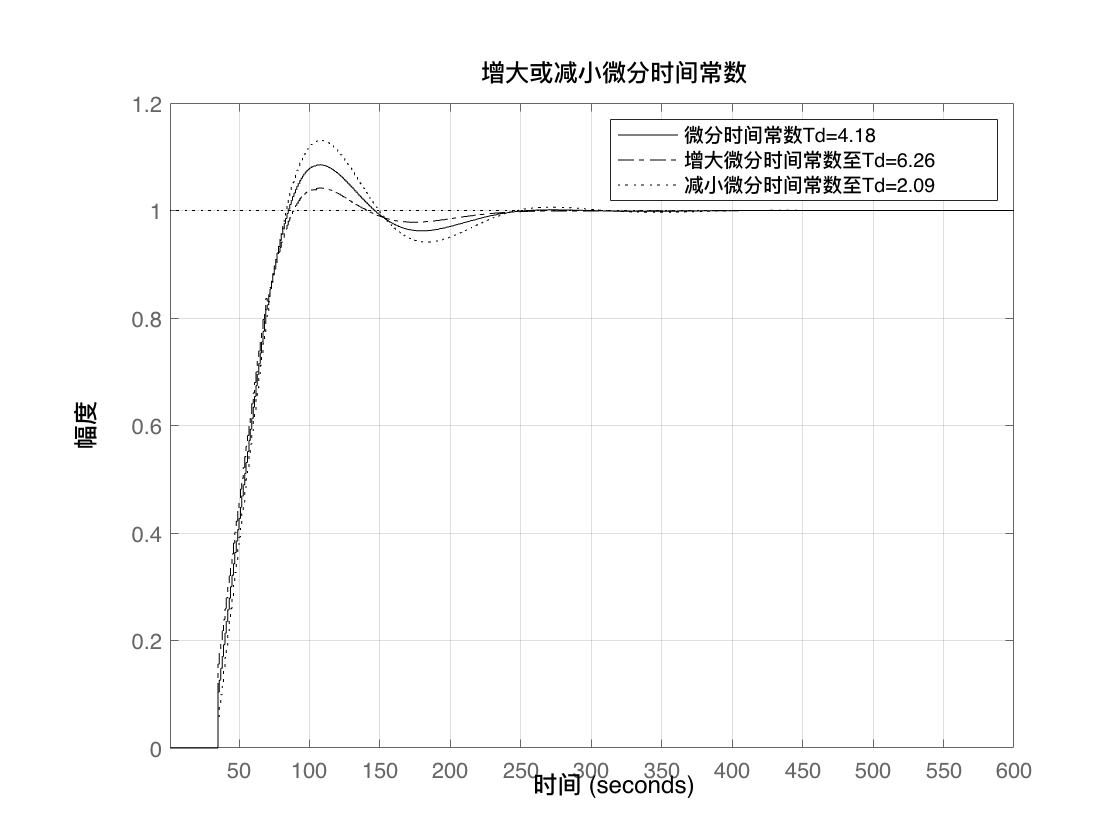

Td=Gpid.Td;
Td_inc=Td*1.5;
Td_dec=Td*0.5;
figure();hold on;
Phi=feedback(series(Gpid,W),1);
Phi1=feedback(series(pidstd(Gpid.Kp,Gpid.Ti,Td_inc,Inf,Ts),W),1);
Phi2=feedback(series(pidstd(Gpid.Kp,Gpid.Ti,Td_dec,Inf,Ts),W),1);
stepplot(Phi,"k-",t)
stepplot(Phi1,"k-.",t)
stepplot(Phi2,"k:",t);
grid;xlabel("时间");ylabel("幅度");
title("增大或减小微分时间常数")
label=[
    sprintf("微分时间常数Td=%.2f",Td);
    sprintf("增大微分时间常数至Td=%.2f",Td_inc);
    sprintf("减小微分时间常数至Td=%.2f",Td_dec)
    ];
legend(label);

T=[struct2table(stepinfo(Phi));struct2table(stepinfo(Phi1));struct2table(stepinfo(Phi2))];
T.Properties.RowNames=label;
T

T = 3×9 table
                              RiseTime    TransientTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
                              ________    _____________    ____________    ___________    ___________    _________    __________    ______    ________

    微分时间常数Td=4.18            41            213             213           0.90883        1.0849         8.491          0         1.0849      107   
    增大微分时间常数至Td=6.26       41            186             186           0.90208        1.0417        4.1742          0         1.0417      107   
    减小微分时间常数至Td=2.09       38            225             225           0.91173        1.1304        13.036          0         1.1304      108   
